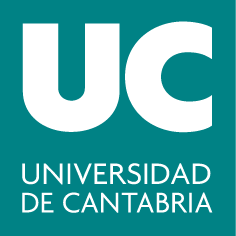

***Grados en Ingeniería Eléctrica y en  Ingeniería en Electrónica Industrial y Automática***

**Cálculo I**

# **7. Series**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

### Series numéricas

#### Sumas (parciales y totales) 

Hemos visto que, salvo para el caso de series geométricas y telescópicas, el cálculo de la suma de cualquier otro tipo de serie suele resultar una tarea poco menos que imposible. En cambio, con MATLAB resulta muy fácil calcular tanto cualquier suma parcial de una serie como su suma total. Para ello se utiliza el comando `symsum`, que opera sobre expresiones simbólicas. 

**Ejemplo:** Consideramos la serie $$\displaystyle\sum_{n=1}^{\infty}\frac{1}{n}$$.

 Calculamos su suma parcial 56-ésima: 

syms n integer  % defino 'n' como variable simbolica (entera)
a_n = 1/n;  % termino general de la serie
S_56 = double(symsum(a_n, n, 1, 56) ) % suma parcial 56-esima (valor numérico)

 Calcula su suma total:

S = symsum(a_n, n, 1, inf)  % suma total

Como la suma total es $\infty$, la serie es divergente.

Como ya sabíamos, la serie $$\displaystyle\sum_{n=1}^{\infty}\frac{1}{n}$$ es divergente (serie armónica con $p = 1$). Otra forma de verlo sería a partir de la expresión (simbólica) de su suma parcial enésima:

syms N integer
a_n = 1/n;
S_N = symsum(a_n, n, 1, N);    % expresion simbolica de la suma parcial enesima

Sabemos que $S = \lim_{n\to \infty} S_n$, entonces la suma total se calcula como

S = limit(S_n, N, inf)          % suma total (serie divergente)

Fíjate en que resulta muy fácil analizar el carácter (convergente o divergente) de cualquier serie con MATLAB.

**Ejercicio:** Analiza el carácter de la siguientes series:

- 
$$$\displaystyle\sum_{n=1}^{\infty}\frac{1}{n(n+1)}$$$


% escribe aquí el código:





Solución:

clearvars
syms n integer
a_n = 1/(n*(n+1));  % termino general
S = double(symsum(a_n, 1, inf))  % convergente (su suma es 1)

- 
$$$\displaystyle\sum_{n=1}^{\infty}\frac{2^n+1}{5^n+1}$$$


% escribe aquí el código:





Solución:

a_n = (2^n + 1)/(5^n + 1);
S = double(symsum(a_n, 1, inf))  % convergente (su suma es 0.8084)

-  $$\displaystyle\sum_{n=1}^{\infty}\frac{3n-1}{(\sqrt{2})^n}$ $(por el criterio del cociente es convergente)

% escribe aquí el código:





Solución:

a_n = (3*n - 1)/(sqrt(2)^n);  % termino general
S = double(symsum(a_n, 1, inf))  % convergente (su suma es 22.3137)

-  $$\displaystyle\sum_{n=1}^{\infty}\frac{(2n)!}{(n!)^2}$$ (por el criterio del cociente es divergente)

% escribe aquí el código:





Solución:

a_n = factorial(2*n)/(factorial(n))^2;  % termino general
S = double(symsum(a_n, 1, inf))   % divergente (MATLAB devuelve NaN/Inf)

#### Término general

Otra cosa que resulta prácticamente inmediata con MATLAB es calcular el término general de una serie, $$a_n$$, conocida la expresión de su suma parcial enésima ($$a_n = S_n - S_{n-1}$$). 

**Ejemplo:** Calculamos el término general de la serie cuya suma parcial enésima es $$S_n = \frac{n+1}{n+10}$$

1.  Definimos la suma parcial enésima:

clearvars
syms n integer
S_n = (n+1)/(n+10)  % suma parcial enesima

2. Calculamos $S_{n-1}$ utilizando el comando `subs`:

S_nmenos1 = subs(S_n, n, n-1)  % suma parcial (n-1)-esima

3. Calculamos el término general $$a_n = S_n - S_{n-1}$$:

a_n = simplify(S_n - S_nmenos1)  % termino general

¿Esta serie es convergente o divergente? Por el criterio de comparación es convergente. Comprobamos calculando la suma total:

S = limit(S_n,n,inf) 

otra opción:

S = symsum(a_n,n,0,inf)

Es importante tener claro que las sucesiones $$\lbrace {a_n} \rbrace$ $y $$\lbrace {S_n} \rbrace$ $no tienen porqué tener el mismo carácter. Resulta evidente para el caso de la serie $$\displaystyle\sum_{n=1}^{\infty}\frac{1}{n}$$:

syms n N integer
a_n = 1/n;  % termino general
limit(a_n, n, inf)  % sucesion convergente
S_N = symsum(a_n, 1, N);  % suma parcial enesima
limit(S_N, N, inf)  % sucesion divergente

### Series de potencias

 La expresión $$\displaystyle\sum_{n=0}^{\infty}a_n(x-a)^n$$ responde a una **serie de potencias** centrada en el punto$ $x=a$$, con $$a$$ constante. Este tipo de series pueden interpretarse como una función de $$x$$: $$$f(x) = \displaystyle\sum_{n=0}^{\infty}a_n(x-a)^n$$$

 El** radio de convergencia** de la serie $$\displaystyle\sum_{n=0}^{\infty}a_n(x-a)^n$ $ viene dado por: 

		
$$$$R = \lim\limits_{n\to \infty} \left|\frac{a_n}{a_{n+1}}\right|$$$$


Dentro del **intervalo de convergencia** $$(a-R, a+R)$$ la serie converge. En los extremos, podrá converger o diverger, por lo que habrá que estudiar específicamente qué sucede en los puntos $$x=a+R$$ y $$x=a-R$$.

El dominio de la función$ $f(x) = \displaystyle\sum_{n=0}^{\infty}a_n(x-a)^n$$ es el conjunto de valores $$x$$ para los que la serie converge.

Basándonos en esta definición, resulta inmediato calcular en MATLAB el intervalo de convergencia para una serie de potencias centrada en el punto $$a$$. Para ello, habrá que calcular $$R$$ y estudiar el carácter de la serie en los puntos ($$x=a-R$$) y ($$x=a+R$$).

**Ejemplo: **Calculamos el intervalo de convergencia para la serie $$\displaystyle\sum_{n=1}^{\infty}\frac{(-1)^{n+1}}{n5^n} (x-5)^n$$.

1. Definimos $a_n$ y término general de la serie:

clearvars
syms n integer
syms x real 
a_n = ((-1)^(n+1)) / (n*5^n);
tgc = a_n*((x-5)^n); % termino general (completo) de la serie

2. Calculamos $a_{n+1}$

a_nmas1 = subs(a_n, n, n+1);

3. Calculamos el radio de convergencia: 

R = limit(abs(a_n/a_nmas1), n, inf)  % radio de convergencia alrededor de a=5

4. Como $R>0$ (en este caso el intervalo de convergencia es el único punto $x=a$) y $R<\infty$(en este caso la serie es convergente para cualquier valor de $x$), estudiamos la convergencia en los extremos del intervalo $$x=a+R$$ y $$x=a-R$$. Primero, considermos el extremo izquierdo ($$x=a-R$$):

a = 5; % centro de la serie
S_izq = symsum(subs(tgc, x, a-R), 1, inf)  % serie divergente en x=5-5

La serie es divergente, no incluimos el punto $x = a-R = 0$ en el intervalo de convergencia.

 Considermos el extremo derecho ($$x=a+R$$):

S_der = symsum(subs(tgc, x, a+R), 1, inf)  % serie convergente en x=5+5

5. Entonces, el intervalo de covergencia sera (0, 10]

### Ejercicios propuestos

Halla el término general y el carácter de las series cuya suma parcial enésima es:

- 
$$ $S_n = \frac{3^{n+1} - 1}{2}$, $n \in \mathbb{N}$ $$
	

- 
$$ $S_n = \frac{2^{n} - 1}{2 \cdot 3^n}$, $n \in \mathbb{N}$ 	$$


% escribe aquí el código:



Solución:

soluciones(1)

2. Analiza la convergencia y halla la suma total de la  serie: $$\displaystyle\sum_{n=1}^{\infty} \frac{2^{n-1}}{4^{2n+1}}$$.

A continuación, representa en un mismo gráfico los 50 primeros términos de las sucesiones$ $\lbrace S_n \rbrace$ $(sumas parciales) y $$\lbrace a_n \rbrace$ $(término general).

% escribe aquí el código:




Solución:

soluciones(2)

3. Considera el siguiente desarrollo en serie de potencias centrado en$ $x=0$$: 


$$$f(x) = -\log(1+x) = \displaystyle\sum_{n=1}^{\infty}\frac{(-1)^{n} x^n}{n}$$$


-  Averigua cuál es el dominio de $$f$$ (conjunto de valores $$x$ $para  los que la serie converge).

- Representa en una misma gráfica $$f$$ y la suma de los 20 primeros términos de la serie en el dominio $$[-0.9,1]$$.

% escribe aquí el código:



Solución:

soluciones(3)

### Resumen

**Sumas Parciales y Totales**

- [`symsum`**:**](https://es.mathworks.com/help/symbolic/sym.symsum.html) Este comando calcula la suma parcial o total de una serie. Puede operar sobre expresiones simbólicas para obtener tanto la suma de un número finito de términos como la suma infinita de la serie.

- `symsum(f, n, a, b)`**:** Calcula la suma de la serie `f` desde `n = a` hasta `n = b`.

- `symsum(f, n, a, inf)`**:** Calcula la suma total de la serie desde `n = a` hasta el infinito.

- Si el resultado es $\infty$ o `NaN`, la serie es divergente. En otro caso es convergente.

**Término General**

- **Término General de la Serie (**`a_n`**)**: Es el término individual de la serie, que se puede obtener a partir de la diferencia entre sumas parciales consecutivas: $$a_n = S_n - S_{n-1}$$

**Series de potencias **$$\displaystyle\sum_{n=0}^{\infty}a_n(x-a)^n$$

- `R = limit(abs(a_n/a_nmas1), n, inf)`**:** Calcula el radio de convergencia `R` para una serie de potencias.

- Para estudiar la convergencia en los extremos del intervalo de convergencia:

siendo `tgc` - término general completo de una serie de potencias, `a` - centro de la serie. 

### Soluciones 

function [] = soluciones(n)
switch n
    case 1
        % Ejercicio 1:
        fprintf("Ejercicio 1:\n");
        syms n integer
        S_n = (3^(n+1)-1)/2
        S_nmenos1 = subs(S_n, n, n-1);  % suma parcial (n-1)-esima
        a_n = simplify(S_n - S_nmenos1)  % termino general
        S = limit(S_n,n,inf)
        fprintf("Como la suma total es inf, la serie es divergente.\n")
        S_n = (2^n-1)/(2*3^n)
        S_nmenos1 = subs(S_n, n, n-1);  % suma parcial (n-1)-esima
        a_n = simplify(S_n - S_nmenos1)  % termino general
        S = limit(S_n,n,inf)
        fprintf("Como la suma total es 0, la serie es convergente.\n")
    case 2
        % Ejercicio 2:
        fprintf("Ejercicio 2:\n");
        close all
        syms n N integer
        a_n = 2^(n-1)/4^(2*n+1);
        S_N = symsum(a_n,n,1,N);
        S = limit(S_N,N, inf);
        fprintf("Como S  = %f, la serie es convergente\n",double(S))
        x = 1:50;
        an = double(subs(a_n, n,x));
        Sn =  double(subs(S_N, N,x));
        plot(x,an,'r-o')
        hold on
        plot(x,Sn,'b-*');
        grid on
        legend('a_n','S_n')
        xlabel('n')
        hold off
    case 3
        % Ejercicio 3:
        fprintf("Ejercicio 3:\n");
        syms x real
        syms n integer
        f(x) = -log(1+x);
        tgc = (-1)^n*x^n/n;
        an = (-1)^n/n;
        anmas1 = subs(an,n,n+1);
        R = double(limit(abs(an/anmas1),n,inf));
        a = 0; % centro de la serie
        S_izq = symsum(subs(tgc, x, a-R), 1, inf)
        S_der = symsum(subs(tgc, x, a+R), 1, inf)
        fprintf(" Radio: R = %f,\n Intervalo de convergencia: (%.2f, %.2f]",R, a-R,a+R)
        S20(x) = symsum(tgc,n,1,20);
        fplot(f,[-0.9,1],'r-','LineWidth',2);
        hold on
        fplot(S20,[-0.9,1],'k--','LineWidth',2);
        hold off
        grid on
end
end